# Final Project : Car Detection in a video

Let's start by exploring some properties of the RoadTraffic.mp4 video : 

vTraffic = VideoReader("RoadTraffic.mp4")

vTraffic =   VideoReader with properties:

   General Properties:
            Name: 'RoadTraffic.mp4'
            Path: 'C:\Users\21692\Desktop\coursera\MATLAB\Image Processing for Engineering and Science\Data\MathWorks Images'
        Duration: 24
     CurrentTime: 0.1000
       NumFrames: 240

   Video Properties:
           Width: 1158
          Height: 518
       FrameRate: 10
    BitsPerPixel: 24
     VideoFormat: 'RGB24'


## Preprocessing the video

The main goal here is to preprocess the video by removing the noise from the frames. 

We'll work with frames 96, 113 and 227 in order to test our function.

We'll produce a function a removes the noise from the frames and converts them to grayscale. The final output will be stored in a new video.

Let's get started.

frame_96 = read(vTraffic,96);
frame_113 = read(vTraffic,113);
frame_227 = read(vTraffic,227);

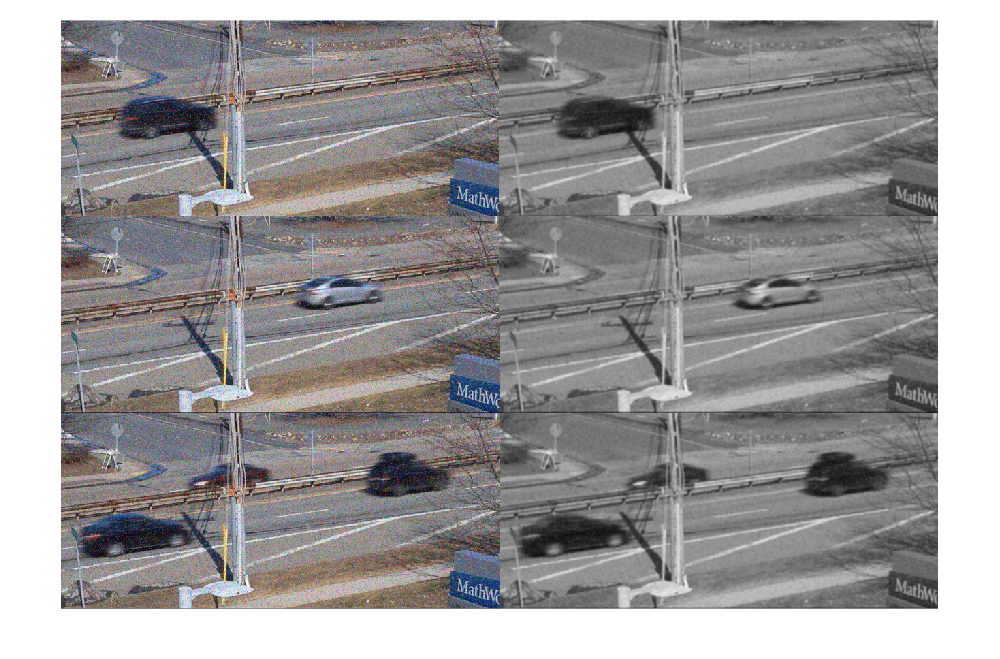

filtered_96 = enhanceImage(frame_96);
filtered_113 = enhanceImage(frame_113);
filtered_227 = enhanceImage(frame_227);

montage({frame_96,filtered_96,frame_113,filtered_113,frame_227,filtered_227})

## Isolating cars

Now that the video is filtered and converted it to grayscale, the next step is to use image segmentation to isolate the cars driving on the road. The end result of this section is to have a process for taking frames from the video and generates segmented masks.

#### Challenge 1: The telephone pole

A significant issue encountered in a few frames is how to account for the telephone pole in front of the road like the 10th frame of the video.

#### Challenge 2: Light vs dark cars

In your grayscale video, cars can be light, dark, or in-between suc as in frame 153.

#### Challenge 3: Overlapping cars

Another challenge is when cars in the two lanes overlap, such as found in frame 225.

Let's move ahead and give it a try.

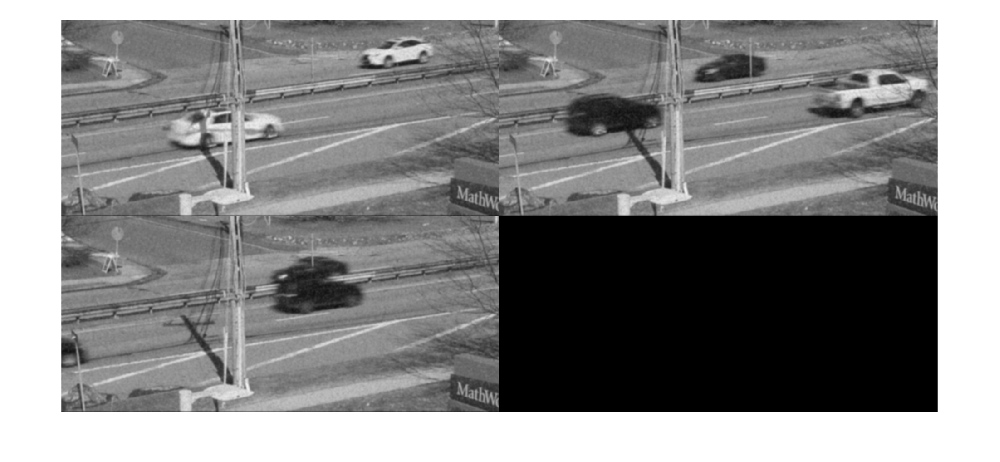

frame_153 = enhanceImage(read(vTraffic,153));
frame_10 = enhanceImage(read(vTraffic,10));
frame_225 = enhanceImage(read(vTraffic,225));
montage({frame_10,frame_153,frame_225})